## Estimar probabilidade + espaço de amostragem

### 5.

Probabilidades batem certo

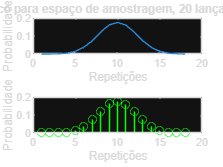

Probabilidades batem certo

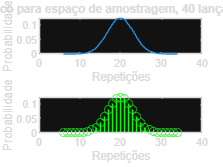

Probabilidades batem certo

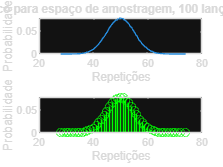

p = 0.5;
lancamentos = [20, 40, 100];
caras = 1;
N = 1e5;
for lan = lancamentos
    [~, amostragem] = prob_simulation(p, lan, caras, N);

    if sum(amostragem(:,2))
        fprintf("Probabilidades batem certo")
    end

    figure;
    subplot(2,1,1);
    plot(amostragem(:,1),amostragem(:,2));    
    xlabel('Repetições');
    ylabel('Probabilidade');
    title(sprintf('Gráfico para espaço de amostragem, %d lançamentos', lan));
    subplot(2,1,2);
    stem(amostragem(:,1),amostragem(:,2),Color="g");
    xlabel('Repetições');
    ylabel('Probabilidade');
end